# Initialization (Refer to "Reference_new.jpg")

close all;
clear all;
clc;

length_pole = 9;                % length of AB
length_extension = 7.2;           % length of CB
length_DE = 4.75;
length_DB = 2.45;

max_slider_height = 5.4;
min_slider_height = 1.88;


increments = 50;
slider_heights = linspace(min_slider_height, max_slider_height, increments);     % represents point E



## Phase 1: Raising slider to open canopy

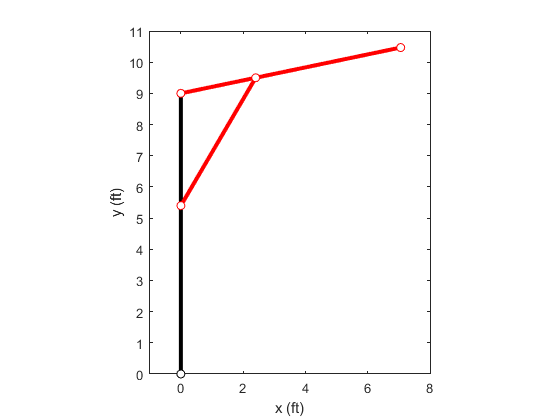

figure(1);

for i= 1:increments
    
    %% Position Calculations
    Ax(i) = 0;
    Ay(i) = 0;
    Bx(i) = 0;
    By(i) = length_pole;
    Ex(i) = 0;
    Ey(i) = slider_heights(i);
    
    a = length_DB;
    b = length_pole - Ey(i);
    c = length_DE;
    
    theta = acos((a^2+b^2-c^2)/(2*a*b));        %% Cosine Law

    Dx(i) = length_DB*sin(theta);
    Dy(i) = length_pole - length_DB*cos(theta);
    Cx(i) = length_extension*sin(theta);
    Cy(i) = length_pole - length_extension*cos(theta);
    
    
    %% Plots
    plot( [Ax(i) Bx(i)], [Ay(i), By(i)],'Color','black','LineWidth',3);
    hold on;
    plot( [Bx(i) Cx(i)], [By(i), Cy(i)],'Color','r','LineWidth',3); 
    plot( [Dx(i) Ex(i)], [Dy(i), Ey(i)],'Color','r','LineWidth',3); 
    plot(Ax(i), Ay(i), 'blacko','MarkerFaceColor','w');
    plot(Bx(i), By(i), 'ro','MarkerFaceColor','w');
    plot(Cx(i), Cy(i), 'ro','MarkerFaceColor','w');
    plot(Dx(i), Dy(i), 'ro','MarkerFaceColor','w');
    plot(Ex(i), Ey(i), 'ro','MarkerFaceColor','w');
    
    hold off;
    
    title("New Design")
    xlabel("x (ft)");
    ylabel("y (ft)");
    xlim([-1 8]);
    ylim([0 11]);
    daspect([1 1 1]);
    
    pause(0.1);
end

## Velocity of Tip

theta2_dot = 3*pi;              % r/s
gear_ratio = 2;
r = 3.5 /2/12;                  % radius of pinion (ft)

w = theta2_dot/gear_ratio;      % angular velocity of pinion (r/s)
v = r*w;                        % linear velocity of rack (ft/s)                    

max_t = (max_slider_height-min_slider_height)/v;
time = linspace(0, max_t, increments);

increment_t = max_t/(increments - 1);       % time per increment


% Velocity of Tip
figure(2);

speed_Cx = diff(Cx)/increment_t;
speed_Cy = diff(Cy)/increment_t;
velocity_C = sqrt(speed_Cx.^2 + speed_Cy.^2);

plot(time, [0 velocity_C]);
xlabel("Time (t)");
title("Velocity of Tip Through Opening Process (ft/s)");



## Stage 2: Tilt adjustment

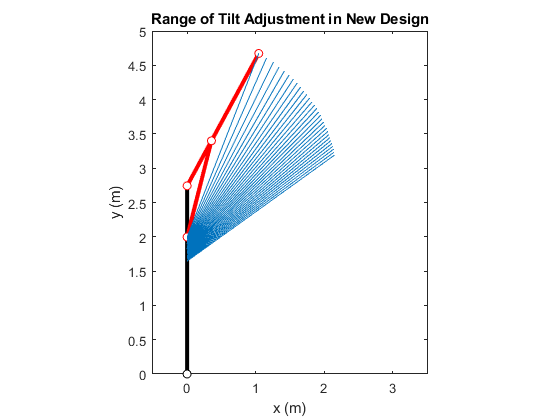

length_pole = 9;                % length of AB
length_extension = 7.2;           % length of CB
length_DE = 4.75;
length_DB = 2.45;

max_slider_height = 6.55;           % found experimentally such that alpha = 14 degrees
min_slider_height = 5.4;

increments = 30;
slider_heights = linspace(min_slider_height, max_slider_height, increments);     % represents point E

figure(1);

for i= 1:increments
    
    %% Position Calculations
    Ax(i) = 0;
    Ay(i) = 0;
    Bx(i) = 0;
    By(i) = length_pole;
    Ex(i) = 0;
    Ey(i) = slider_heights(i);
    
    a = length_DB;
    b = length_pole - Ey(i);
    c = length_DE;
    
    theta = acos((a^2+b^2-c^2)/(2*a*b));

    Dx(i) = length_DB*sin(theta);
    Dy(i) = length_pole - length_DB*cos(theta);
    Cx(i) = length_extension*sin(theta);
    Cy(i) = length_pole - length_extension*cos(theta);
    
    
    %% Convert from ft to m
    Ax(i) = Ax(i) * 0.3048;
    Ay(i) = Ay(i) * 0.3048;
    Bx(i) = Bx(i) * 0.3048;
    By(i) = By(i) * 0.3048;
    Cx(i) = Cx(i) * 0.3048;
    Cy(i) = Cy(i) * 0.3048;
    Dx(i) = Dx(i) * 0.3048;
    Dy(i) = Dy(i) * 0.3048;
    Ex(i) = Ex(i) * 0.3048;
    Ey(i) = Ey(i) * 0.3048;

    %% Plots
    plot( [Ax(i) Bx(i)], [Ay(i), By(i)],'Color','black','LineWidth',3);
    hold on;
    plot( [Bx(i) Cx(i)], [By(i), Cy(i)],'Color','r','LineWidth',3); 
    plot( [Dx(i) Ex(i)], [Dy(i), Ey(i)],'Color','r','LineWidth',3); 
    plot(Ax(i), Ay(i), 'blacko','MarkerFaceColor','w');
    plot(Bx(i), By(i), 'ro','MarkerFaceColor','w');
    plot(Cx(i), Cy(i), 'ro','MarkerFaceColor','w');
    plot(Dx(i), Dy(i), 'ro','MarkerFaceColor','w');
    plot(Ex(i), Ey(i), 'ro','MarkerFaceColor','w');
    
    for j= 1:i
        line([Cx(j) Ex(j)],[Cy(j) Ey(j)]);      % Draws angle trajectories
    end
    
    hold off;
    
    title("Range of Tilt Adjustment in New Design");
    xlabel("x (m)");
    ylabel("y (m)");
    xlim([-0.5 3.5]);
    ylim([0 5]);
    daspect([1 1 1]);
    
    pause(0.1);
end



max_canopy_angle = atan((Cy(i) - Ey(i))/Cx(i) - Ex(i)) *180/pi

max_canopy_angle = 68.6798

min_canopy_angle = atan((Cy(1) - Ey(1))/Cx(1) - Ex(1)) *180/pi

min_canopy_angle = 35.7244

angle_range = 32.9554


alpha = asin(length_DB*sin(theta)/length_DE) *180/pi

alpha = 14.2134